
%% SMART CLOUD RESOURCE ALLOCATION AND COMPETITIVE STRATEGY
% Linear Programming and Game Theory
% MATLAB Live Script Demonstration

clc;
close all;

% Identify the project folder
projectRoot = pwd;

% Add project folders to MATLAB path
addpath(projectRoot);
addpath(genpath(fullfile(projectRoot, 'src')));
addpath(genpath(fullfile(projectRoot, 'data')));

% Check required files
requiredFiles = {
    'main.m'
    'src/solveLP.m'
    'src/analyzeGame.m'
    'src/sensitivityAnalysis.m'
    'src/plotResults.m'
    };

fprintf('Checking project files...\n\n');

Checking project files...




for k = 1:length(requiredFiles)

    filePath = fullfile(projectRoot, requiredFiles{k});

    if isfile(filePath)
        fprintf('FOUND: %s\n', requiredFiles{k});
    else
        error('Missing project file: %s', requiredFiles{k});
    end

end

FOUND: main.m
FOUND: src/solveLP.m
FOUND: src/analyzeGame.m
FOUND: src/sensitivityAnalysis.m
FOUND: src/plotResults.m



fprintf('\nProject setup completed successfully!\n');


Project setup completed successfully!





%% LINEAR PROGRAMMING - CLOUD RESOURCE ALLOCATION

% Step 1: Define cloud server parameters

serverNames = {'Server A'; 'Server B'; 'Server C'};

capacity = [100; 80; 60];

unitCost = [4; 3; 2.5];

totalDemand = 180;


% Step 2: Formulate the Linear Programming problem
%
% Minimize:
% Z = 4*x1 + 3*x2 + 2.5*x3
%
% Subject to:
% x1 + x2 + x3 = 180
% x1 <= 100
% x2 <= 80
% x3 <= 60
% x1, x2, x3 >= 0

f = unitCost;

A = eye(3);
b = capacity;

Aeq = [1 1 1];
beq = totalDemand;

lb = zeros(3,1);
ub = [];


% Step 3: Display the mathematical model

disp('LINEAR PROGRAMMING MODEL');

LINEAR PROGRAMMING MODEL



fprintf('\nObjective Function:\n');


Objective Function:


fprintf('Minimize Z = 4*x1 + 3*x2 + 2.5*x3\n');

Minimize Z = 4*x1 + 3*x2 + 2.5*x3



fprintf('\nTotal Workload Demand = %d units\n', totalDemand);


Total Workload Demand = 180 units



disp('Server Capacity Constraints:');

Server Capacity Constraints:


disp(A);

     1     0     0
     0     1     0
     0     0     1



disp(b);

   100
    80
    60





% Step 4: Solve the optimization problem

options = optimoptions('linprog', 'Display', 'none');

[x, minCost, exitflag, output, lambda] = ...
    linprog(f, A, b, Aeq, beq, lb, ub, options);


% Step 5: Check whether an optimal solution was found

if exitflag <= 0
    error('Optimization failed. Check the input parameters.');
end

fprintf('\nOPTIMAL SOLUTION FOUND!\n');


OPTIMAL SOLUTION FOUND!




% Step 6: Calculate server utilization

utilization = (x ./ capacity) * 100;

remainingCapacity = capacity - x;

workloadCost = x .* unitCost;


% Step 7: Display the results

resultsTable = table( ...
    serverNames, ...
    capacity, ...
    x, ...
    remainingCapacity, ...
    unitCost, ...
    workloadCost, ...
    utilization, ...
    'VariableNames', { ...
    'Server', ...
    'Capacity', ...
    'AllocatedWorkload', ...
    'RemainingCapacity', ...
    'UnitCost', ...
    'TotalCost', ...
    'UtilizationPercent'});

disp('CLOUD RESOURCE ALLOCATION RESULTS:');

CLOUD RESOURCE ALLOCATION RESULTS:


disp(resultsTable);

       Server       Capacity    AllocatedWorkload    RemainingCapacity    UnitCost    TotalCost    UtilizationPercent
    ____________    ________    _________________    _________________    ________    _________    __________________

    {'Server A'}      100              40                   60                4          160               40        
    {'Server B'}       80              80                    0                3          240              100        
    {'Server C'}       60              60                    0              2.5          150              100        




fprintf('\nMinimum Total Operating Cost = Rs. %.2f\n', minCost);


Minimum Total Operating Cost = Rs. 550.00



fprintf('Total Allocated Workload = %.2f units\n', sum(x));

Total Allocated Workload = 180.00 units


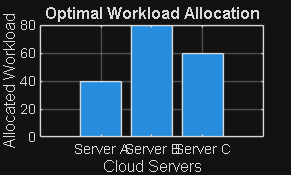



% Step 8: Visualize workload allocation

figure('Name', 'Cloud Workload Allocation');

bar(x);

title('Optimal Workload Allocation');
xlabel('Cloud Servers');
ylabel('Allocated Workload');

xticklabels(serverNames);

grid on;

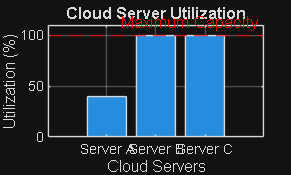



% Step 9: Visualize server utilization

figure('Name', 'Server Utilization');

bar(utilization);

title('Cloud Server Utilization');
xlabel('Cloud Servers');
ylabel('Utilization (%)');

xticklabels(serverNames);

ylim([0 110]);

yline(100, '--r', 'Maximum Capacity');

grid on;



% Step 10: Display completion message

disp('Linear Programming Analysis Completed Successfully.');

Linear Programming Analysis Completed Successfully.




%% GAME THEORY - COMPETITIVE CLOUD PRICING

clc;

% STEP 1: Define available strategies

strategies = {'Low Price', 'High Price'};

% STEP 2: Define payoff matrices
%
% Rows represent Provider A strategies.
% Columns represent Provider B strategies.
%
% Provider A payoff matrix:

payoffA = [
    40  70;
    20  60
];

% Provider B payoff matrix:

payoffB = [
    40  20;
    70  60
];


% STEP 3: Display payoff matrices

disp('PROVIDER A PAYOFF MATRIX');

PROVIDER A PAYOFF MATRIX


disp(array2table(payoffA, ...
    'RowNames', strategies, ...
    'VariableNames', {'B_Low', 'B_High'}));

                  B_Low    B_High
                  _____    ______

    Low Price      40        70  
    High Price     20        60  




disp('PROVIDER B PAYOFF MATRIX');

PROVIDER B PAYOFF MATRIX


disp(array2table(payoffB, ...
    'RowNames', strategies, ...
    'VariableNames', {'B_Low', 'B_High'}));

                  B_Low    B_High
                  _____    ______

    Low Price      40        20  
    High Price     70        60  





% STEP 4: Find best responses

% Provider A: Best response for each strategy of B

bestResponseA = false(2,2);

for j = 1:2
    bestValue = max(payoffA(:,j));
    bestResponseA(:,j) = payoffA(:,j) == bestValue;
end

% Provider B: Best response for each strategy of A

bestResponseB = false(2,2);

for i = 1:2
    bestValue = max(payoffB(i,:));
    bestResponseB(i,:) = payoffB(i,:) == bestValue;
end


% STEP 5: Identify pure-strategy Nash equilibrium

nashEquilibrium = bestResponseA & bestResponseB;

[rowNE, colNE] = find(nashEquilibrium);

disp('PURE STRATEGY NASH EQUILIBRIUM');

PURE STRATEGY NASH EQUILIBRIUM



if isempty(rowNE)

    disp('No pure-strategy Nash equilibrium found.');

else

    for k = 1:length(rowNE)

        i = rowNE(k);
        j = colNE(k);

        fprintf('\nNash Equilibrium %d:\n', k);

        fprintf('Provider A: %s\n', strategies{i});
        fprintf('Provider B: %s\n', strategies{j});

        fprintf('Provider A Payoff: %.2f\n', payoffA(i,j));
        fprintf('Provider B Payoff: %.2f\n', payoffB(i,j));

    end

end


Nash Equilibrium 1:


Provider A: Low Price


Provider B: Low Price


Provider A Payoff: 40.00


Provider B Payoff: 40.00




% STEP 6: Check dominant strategies

disp('DOMINANT STRATEGY ANALYSIS');

DOMINANT STRATEGY ANALYSIS



% Provider A

if all(bestResponseA(1,:))
    fprintf('Provider A dominant strategy: Low Price\n');
elseif all(bestResponseA(2,:))
    fprintf('Provider A dominant strategy: High Price\n');
else
    fprintf('Provider A has no strictly dominant strategy.\n');
end

Provider A dominant strategy: Low Price



% Provider B

if all(bestResponseB(:,1))
    fprintf('Provider B dominant strategy: Low Price\n');
elseif all(bestResponseB(:,2))
    fprintf('Provider B dominant strategy: High Price\n');
else
    fprintf('Provider B has no strictly dominant strategy.\n');
end

Provider B dominant strategy: Low Price


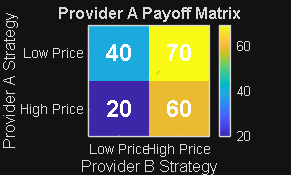



% STEP 7: Visualize Provider A payoff matrix

figure('Name','Provider A Payoff Matrix');

imagesc(payoffA);

colorbar;

title('Provider A Payoff Matrix');

xlabel('Provider B Strategy');
ylabel('Provider A Strategy');

xticks(1:2);
yticks(1:2);

xticklabels(strategies);
yticklabels(strategies);

for i = 1:2
    for j = 1:2
        text(j,i,num2str(payoffA(i,j)), ...
            'HorizontalAlignment','center', ...
            'FontSize',14, ...
            'FontWeight','bold', ...
            'Color','white');
    end
end

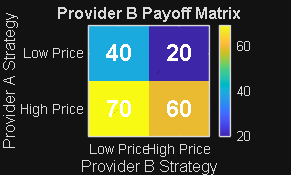



% STEP 8: Visualize Provider B payoff matrix

figure('Name','Provider B Payoff Matrix');

imagesc(payoffB);

colorbar;

title('Provider B Payoff Matrix');

xlabel('Provider B Strategy');
ylabel('Provider A Strategy');

xticks(1:2);
yticks(1:2);

xticklabels(strategies);
yticklabels(strategies);

for i = 1:2
    for j = 1:2
        text(j,i,num2str(payoffB(i,j)), ...
            'HorizontalAlignment','center', ...
            'FontSize',14, ...
            'FontWeight','bold', ...
            'Color','white');
    end
end

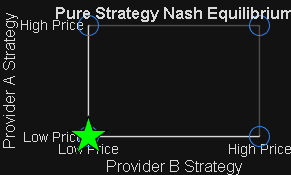



% STEP 9: Highlight Nash equilibrium

if ~isempty(rowNE)

    figure('Name','Nash Equilibrium');

    hold on;

    for i = 1:2
        for j = 1:2

            plot(j,i,'o', ...
                'MarkerSize',12, ...
                'Color',[0.2 0.5 0.9]);

            if nashEquilibrium(i,j)
                plot(j,i,'p', ...
                    'MarkerSize',24, ...
                    'MarkerFaceColor','green', ...
                    'MarkerEdgeColor','black');
            end

        end
    end

    title('Pure Strategy Nash Equilibrium');

    xlabel('Provider B Strategy');
    ylabel('Provider A Strategy');

    xticks(1:2);
    yticks(1:2);

    xticklabels(strategies);
    yticklabels(strategies);

    grid on;
    hold off;

end



% STEP 10: Final output

disp('-----------------------------------');

-----------------------------------


disp('GAME THEORY ANALYSIS COMPLETED');

GAME THEORY ANALYSIS COMPLETED


disp('-----------------------------------');

-----------------------------------




%% SENSITIVITY ANALYSIS - WORKLOAD DEMAND

% Define server parameters
serverNames = {'Server A'; 'Server B'; 'Server C'};
capacity = [100; 80; 60];
unitCost = [4; 3; 2.5];

% Different workload demand scenarios (240 = full capacity, 250 = infeasible test)
demands = [100 140 180 220 240 250];

% Initialize result variables
minimumCosts = zeros(length(demands), 1);
workloadAllocation = zeros(length(demands), 3);
status = strings(length(demands), 1);

% LP constraints
f = unitCost;
A = eye(3);
b = capacity;
Aeq = [1 1 1];
lb = zeros(3, 1);
ub = [];

options = optimoptions('linprog', 'Display', 'none');

% Run sensitivity analysis
for k = 1:length(demands)
    beq = demands(k);
    [x, cost, exitflag] = linprog(f, A, b, Aeq, beq, lb, ub, options);

    if exitflag > 0
        minimumCosts(k) = cost;
        workloadAllocation(k, :) = x';
        status(k) = "Optimal";
    else
        minimumCosts(k) = NaN;
        workloadAllocation(k, :) = [NaN NaN NaN];
        status(k) = "Infeasible";
    end
end

% Create results table (includes the 250 infeasible row)
sensitivityResults = table( ...
    demands', ...
    minimumCosts, ...
    status, ...
    workloadAllocation(:, 1), ...
    workloadAllocation(:, 2), ...
    workloadAllocation(:, 3), ...
    'VariableNames', { ...
    'Demand', ...
    'MinimumCost', ...
    'Status', ...
    'ServerA', ...
    'ServerB', ...
    'ServerC'});

disp('SENSITIVITY ANALYSIS RESULTS');

SENSITIVITY ANALYSIS RESULTS


disp(sensitivityResults);

    Demand    MinimumCost       Status       ServerA    ServerB    ServerC
    ______    ___________    ____________    _______    _______    _______

     100          270        "Optimal"           0         40         60  
     140          390        "Optimal"           0         80         60  
     180          550        "Optimal"          40         80         60  
     220          710        "Optimal"          80         80         60  
     240          790        "Optimal"         100         80         60  
     250          NaN        "Infeasible"      NaN        NaN        NaN  



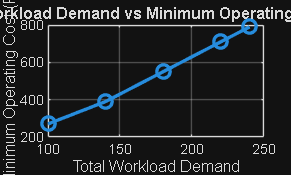


% Filter valid feasible scenarios so charts render cleanly without NaN gaps
valid = ~isnan(minimumCosts);

% Plot demand versus minimum cost
figure('Name', 'Demand vs Minimum Cost');
plot(demands(valid), minimumCosts(valid), '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 8);
title('Workload Demand vs Minimum Operating Cost');
xlabel('Total Workload Demand');
ylabel('Minimum Operating Cost (Rs.)');
grid on;

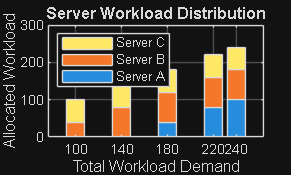


% Plot workload distribution
figure('Name', 'Workload Distribution');
bar(demands(valid), workloadAllocation(valid, :), 'stacked');
title('Server Workload Distribution');
xlabel('Total Workload Demand');
ylabel('Allocated Workload');
legend(serverNames, 'Location', 'northwest');
grid on;


disp('Sensitivity Analysis Completed Successfully.');

Sensitivity Analysis Completed Successfully.



%% DISCUSSION AND CONCLUSION

% 1. Linear Programming Resource Allocation:
%    Because Server C has the lowest unit cost (2.5), the optimizer saturates it
%    first (up to 60 units), followed by Server B (cost 3.0, up to 80 units),
%    and finally Server A (cost 4.0, up to 100 units). Total operating cost rises
%    piecewise-linearly from Rs. 270 (at D = 100) to Rs. 790 (at D = 240).
%    Any demand above the combined 240-unit system capacity (such as D = 250)
%    is flagged as Infeasible.
%
% 2. Competitive Game Theory Pricing:
%    In the two-provider pricing game, 'Low Price' is a strictly dominant
%    strategy for both Provider A and Provider B, resulting in a unique
%    pure-strategy Nash equilibrium at (Low Price, Low Price) with payoffs (40, 40).
%
% 3. Model Scope & Assumptions:
%    All server capacities, unit costs, and provider payoffs are illustrative
%    academic datasets, and the operational LP and strategic Game Theory modules
%    are evaluated as independent decision problems.